clc 
clear all

Define the position of the UWB

N_0 = [1;-1];
N_1 = [6;4];
N_2 = [1;2];

N = [N_0, N_1, N_2]

N =      1     6     1
    -1     4     2


Build the symmetric squared Euclidean distance matrix

D = zeros(size(N,2), size(N,2));
for i = 1:size(N,2)
    for j = 1:size(N,2)
        D(i,j) = norm(N(:,i) - N(:,j))^2;
    end
end

D

D =          0   50.0000    9.0000
   50.0000         0   29.0000
    9.0000   29.0000         0


Compute the Gram matrix

% The Gram matrix is defined as G = -1/2 * H * D * H
% where H = I - 1/n * 1 * 1^T

n = size(D,1)

n = 3

H = eye(n) - 1/n * ones(n,n)

H =     0.6667   -0.3333   -0.3333
   -0.3333    0.6667   -0.3333
   -0.3333   -0.3333    0.6667


G = -1/2 * H * D * H

G =     9.8889  -11.7778    1.8889
  -11.7778   16.5556   -4.7778
    1.8889   -4.7778    2.8889


rank(G)

ans = 2

Compute the eigenvalues and eigenvectors of the Gram matrix

[U, V] = eig(G)

U =    -0.5814    0.5774   -0.5733
    0.7872    0.5774   -0.2169
   -0.2058    0.5774    0.7901


V =    26.5035         0         0
         0    0.0000         0
         0         0    2.8298



% extract the eigenvectors corresponding to the eigenvalues different from 0
U = U(:,diag(V) > 1e-6)

U =    -0.5814   -0.5733
    0.7872   -0.2169
   -0.2058    0.7901


V = V(diag(V) > 1e-6, diag(V) > 1e-6)

V =    26.5035         0
         0    2.8298




P = (U * sqrt(V))'

P =    -2.9931    4.0525   -1.0593
   -0.9644   -0.3648    1.3292



P'*P

ans =     9.8889  -11.7778    1.8889
  -11.7778   16.5556   -4.7778
    1.8889   -4.7778    2.8889


Plot 

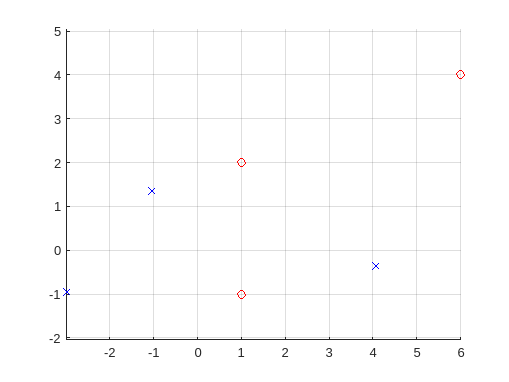

figure;
hold on;
plot(N(1,:), N(2,:), 'ro');
plot(P(1,:), P(2,:), 'bx');
hold off;
axis equal;
grid on;